### Linear Algebra and Programming Skills

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Solving a system of ODEs

The well known [SIRD model](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRD_model) is a system of 4 Ordinary Differential Equations (ODEs) that model the dynamics of an epidemic, e.g., the flu.


$$\frac{dS}{dt} = -\frac{\beta I S}{N}, \\
\frac{dI}{dt} = \frac{\beta I S}{N} - \gamma I - \mu I, \\
\frac{dR}{dt} = \gamma I, \\
\frac{dD}{dt} = \mu I.$$


where $S$ is the number of people susceptible to the virus, $I$is the number of people infected, $R$ is the number of people who have recovered, $D$ is the number of people who have died and $N= S+I+R+D$ is the total number of people in the population. The model parameters are $\beta$, $\gamma$ and $\mu$ which are the rates of infection, recovery and mortality respectively.

The program below solves the SIRD system for the initial value problem $S(0)=999$, $I(0)=1$, $R(0)=D(0)=0$ with $\beta=0.3$, $\gamma = 0.05$ and $\mu=0.01$ using a Runge-Kutta method.

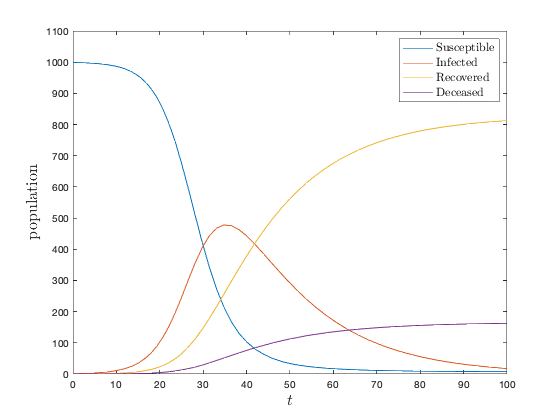

% Define IVP
y0 = [999, 1, 0, 0];
tspan = [0, 100];
beta = 0.3;
gamma = 0.05;
mu = 0.01;

% Solve IVP (using 4/5th order Runge-Kutta method)
[t, y] = ode45(@(t, y)SIRD_model(t, y, beta, gamma, mu), tspan, y0);

% Plot solution
plot(t, y)
axis([tspan, 0, 1100])
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('population', 'Interpreter', 'latex', 'FontSize', 16)
legend('Susceptible', 'Infected', 'Recovered', 'Deceased', ...
    'Interpreter', 'latex', 'FontSize', 12)

The SIRD function is defined below.

function dydt = SIRD_model(~, y, beta, gamma, mu)

% This function defines the SIRD system of ODEs

% Unpack y array
S = y(1);
I = y(2);
N = sum(y);

% Define SIRD system
dydt = zeros(4, 1);
dydt(1) = -beta * I * S / N;
dydt(2) = beta * I * S / N - gamma * I - mu * I;
dydt(3) = gamma * I;
dydt(4) = mu * I;

end